%Messwerte des Verfahren 1
data_jan = readtable("MSA_Verfahren1_200ml_Jan.csv")

data_jan = 25×1 table
    Gewicht_in_g
    ____________

    199         
    213         
    185         
    198         
    205         
    191         
    184         
    193         
    199         
    206         
    207         
    210         
    213         
    197         
    205         
    203         


data_benni = readtable("MSA_Verfahren1_200ml_Benjamin.csv")

data_benni = 25×1 table
    Gewicht_in_g
    ____________

    195         
    199         
    201         
    209         
    192         
    193         
    199         
    192         
    201         
    202         
    205         
    210         
    196         
    197         
    195         
    192         


data_anna = readtable("MSA_Verfahren1_200ml_Anna.csv")

data_anna = 25×1 table
    Gewicht_in_g
    ____________

    201         
    194         
    192         
    195         
    195         
    204         
    201         
    202         
    195         
    201         
    203         
    201         
    198         
    202         
    200         
    204         


data_michael = readtable("MSA_Verfahren1_200ml_Michael.csv")

data_michael = 25×1 table
    Gewicht_in_g
    ____________

    205         
    209         
    210         
    204         
    208         
    209         
    208         
    206         
    208         
    205         
    202         
    209         
    204         
    207         
    208         
    204         



%Statistische Kenngrößen
Mean_Jan = mean(data_jan.Gewicht_in_g)

Mean_Jan = 200.0400

Std_Jan = std(data_jan.Gewicht_in_g)

Std_Jan = 7.8818

Mean_Benni = mean(data_benni.Gewicht_in_g)

Mean_Benni = 198.7200

Std_Benni = std(data_benni.Gewicht_in_g)

Std_Benni = 5.0705

Mean_Anna = mean(data_anna.Gewicht_in_g)

Mean_Anna = 199.7600

Std_Anna = std(data_anna.Gewicht_in_g)

Std_Anna = 3.6774

Mean_Michael = mean(data_michael.Gewicht_in_g)

Mean_Michael = 206.8800

Std_Michael = std(data_michael.Gewicht_in_g)

Std_Michael = 2.2045

## Messmittel der verschiedenen Kandidaten

cg_Jan = 0.2 * 500 / (6*Std_Jan)

cg_Jan = 2.1146

cg_k_Jan = ((0.2/2)*500-abs(Mean_Jan-200))/(3*Std_Jan)

cg_k_Jan = 2.1129

cg_Benni = 0.2 * 500 / (6*Std_Benni)

cg_Benni = 3.2870

cg_k_Benni = ((0.2/2)*500-abs(Mean_Benni-200))/(3*Std_Benni)

cg_k_Benni = 3.2028

cg_Anna = 0.2 * 500 / (6*Std_Anna)

cg_Anna = 4.5322

cg_anna_matlab = capability(data_anna.Gewicht_in_g,[0,200])

cg_anna_matlab = struct with fields:
       mu: 199.7600
    sigma: 3.6774
        P: 0.5260
       Pl: 0
       Pu: 0.4740
       Cp: 9.0644
      Cpl: 18.1070
      Cpu: 0.0218
      Cpk: 0.0218


cg_k_Anna = ((0.2/2)*500-abs(Mean_Anna-200))/(3*Std_Anna)

cg_k_Anna = 4.5104

cg_Michael = 0.2 * 500 / (6*Std_Michael)

cg_Michael = 7.5602

cg_k_Michael = ((0.2/2)*500-abs(Mean_Michael-200))/(3*Std_Michael)

cg_k_Michael = 6.5199


x = (1:1:25)

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


% Frau Neff passen diese Werte ? T = 500 oder T=200? Versuch haben wir mit 200 ml gemacht,
% aber Versuch 2 mit 100-500 ml in 100ml-Schritten

## Lineare Anpassung

linreg_jan = fitlm(x,data_jan.Gewicht_in_g,"linear")

linreg_jan = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)      199.36     3.3157     60.126    8.4599e-27
    x1             0.052308    0.22304    0.23452       0.81665


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 8.04
R-squared: 0.00239,  Adjusted R-Squared -0.041
F-statistic vs. constant model: 0.055, p-value = 0.817

linreg_anna = fitlm(x,data_anna.Gewicht_in_g,"linear")

linreg_anna = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     197.49       1.4512    136.09    6.1999e-35
    x1             0.17462     0.097617    1.7888      0.086832


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 3.52
R-squared: 0.122,  Adjusted R-Squared 0.084
F-statistic vs. constant model: 3.2, p-value = 0.0868

linreg_benni = fitlm(x,data_benni.Gewicht_in_g,"linear")

linreg_benni = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)       199.38     2.1298      93.615    3.3318e-31
    x1             -0.050769    0.14326    -0.35437       0.72629


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 5.17
R-squared: 0.00543,  Adjusted R-Squared -0.0378
F-statistic vs. constant model: 0.126, p-value = 0.726

linreg_michael = fitlm(x,data_michael.Gewicht_in_g,"linear")

linreg_michael = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    ________    _________    __________

    (Intercept)         206.9     0.92849       222.83    7.4203e-40
    x1             -0.0015385    0.062457    -0.024632       0.98056


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 2.25
R-squared: 2.64e-05,  Adjusted R-Squared -0.0435
F-statistic vs. constant model: 0.000607, p-value = 0.981



slope_jan = linreg_jan.Coefficients.Estimate(2)

slope_jan = 0.0523

intercept_jan = linreg_jan.Coefficients.Estimate(1)

intercept_jan = 199.3600

y_jan = slope_jan * x + intercept_jan

y_jan =   199.4123  199.4646  199.5169  199.5692  199.6215  199.6738  199.7262  199.7785  199.8308  199.8831  199.9354  199.9877  200.0400  200.0923  200.1446  200.1969  200.2492  200.3015  200.3538  200.4062  200.4585  200.5108  200.5631  200.6154  200.6677



slope_anna = linreg_anna.Coefficients.Estimate(2)

slope_anna = 0.1746

intercept_anna = linreg_anna.Coefficients.Estimate(1)

intercept_anna = 197.4900

y_anna = slope_anna * x + intercept_anna

y_anna =   197.6646  197.8392  198.0138  198.1885  198.3631  198.5377  198.7123  198.8869  199.0615  199.2362  199.4108  199.5854  199.7600  199.9346  200.1092  200.2838  200.4585  200.6331  200.8077  200.9823  201.1569  201.3315  201.5062  201.6808  201.8554



slope_benni = linreg_benni.Coefficients.Estimate(2)

slope_benni = -0.0508

intercept_benni = linreg_benni.Coefficients.Estimate(1)

intercept_benni = 199.3800

y_benni = slope_benni * x + intercept_benni

y_benni =   199.3292  199.2785  199.2277  199.1769  199.1262  199.0754  199.0246  198.9738  198.9231  198.8723  198.8215  198.7708  198.7200  198.6692  198.6185  198.5677  198.5169  198.4662  198.4154  198.3646  198.3138  198.2631  198.2123  198.1615  198.1108



slope_michael = linreg_michael.Coefficients.Estimate(2)

slope_michael = -0.0015

intercept_michael = linreg_michael.Coefficients.Estimate(1)

intercept_michael = 206.9000

y_michael = slope_michael * x + intercept_michael

y_michael =   206.8985  206.8969  206.8954  206.8938  206.8923  206.8908  206.8892  206.8877  206.8862  206.8846  206.8831  206.8815  206.8800  206.8785  206.8769  206.8754  206.8738  206.8723  206.8708  206.8692  206.8677  206.8662  206.8646  206.8631  206.8615


%%% Plot MSA

hold on
ms1_jan = plot(x,data_jan.Gewicht_in_g,"rx")

ms1_jan =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'x'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25]
              YData: [199 213 185 198 205 191 184 193 199 206 207 210 213 197 205 203 196 206 197 204 210 193 195 196 196]
              ZData: [1×0 double]

  Show all properties


plt_linreg_jan = plot(x, y_jan)

plt_linreg_jan =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25]
              YData: [199.4123 199.4646 199.5169 199.5692 199.6215 199.6738 199.7262 199.7785 199.8308 199.8831 199.9354 199.9877 200.0400 200.0923 200.1446 200.1969 200.2492 200.3015 200.3538 200.4062 200.4585 200.5108 200.5631 200.6154 200.6677]
              ZData: [1×0 double]

  Show all properties




ms1_anna = plot(x,data_anna.Gewicht_in_g, "go")

ms1_anna =   Line with properties:

              Color: [0 1 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25]
              YData: [201 194 192 195 195 204 201 202 195 201 203 201 198 202 200 204 205 201 201 195 203 204 197 198 202]
              ZData: [1×0 double]

  Show all properties


plt_linreg_anna = plot(x, y_anna)

plt_linreg_anna =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25]
              YData: [197.6646 197.8392 198.0138 198.1885 198.3631 198.5377 198.7123 198.8869 199.0615 199.2362 199.4108 199.5854 199.7600 199.9346 200.1092 200.2838 200.4585 200.6331 200.8077 200.9823 201.1569 201.3315 201.5062 201.6808 201.8554]
              ZData: [1×0 double]

  Show all properties



ms1_benni = plot(x, data_benni.Gewicht_in_g, "b+")

ms1_benni =   Line with properties:

              Color: [0 0 1]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '+'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25]
              YData: [195 199 201 209 192 193 199 192 201 202 205 210 196 197 195 192 202 205 200 202 198 193 195 196 199]
              ZData: [1×0 double]

  Show all properties


plt_linreg_benni = plot(x, y_benni)

plt_linreg_benni =   Line with properties:

              Color: [0.9290 0.6940 0.1250]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25]
              YData: [199.3292 199.2785 199.2277 199.1769 199.1262 199.0754 199.0246 198.9738 198.9231 198.8723 198.8215 198.7708 198.7200 198.6692 198.6185 198.5677 198.5169 198.4662 198.4154 198.3646 198.3138 198.2631 198.2123 198.1615 198.1108]
              ZData: [1×0 double]

  Show all properties



ms1_michael = plot(x, data_michael.Gewicht_in_g, "ms")

ms1_michael =   Line with properties:

              Color: [1 0 1]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'square'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25]
              YData: [205 209 210 204 208 209 208 206 208 205 202 209 204 207 208 204 210 206 209 206 204 209 206 208 208]
              ZData: [1×0 double]

  Show all properties


plt_linreg_michael = plot(x, y_michael)

plt_linreg_michael =   Line with properties:

              Color: [0.4940 0.1840 0.5560]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25]
              YData: [206.8985 206.8969 206.8954 206.8938 206.8923 206.8908 206.8892 206.8877 206.8862 206.8846 206.8831 206.8815 206.8800 206.8785 206.8769 206.8754 206.8738 206.8723 206.8708 206.8692 206.8677 206.8662 206.8646 206.8631 206.8615]
              ZData: [1×0 double]

  Show all properties


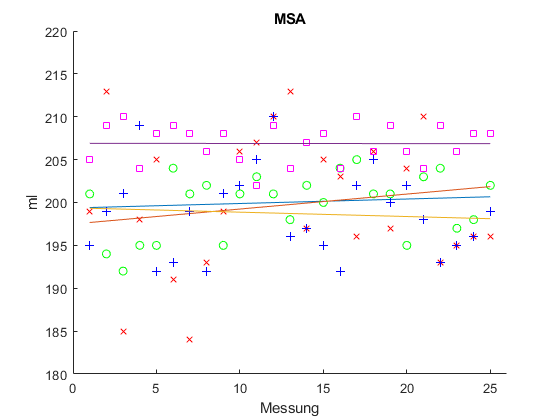


hold off
title("MSA");
xlabel("Messung");
ylabel("ml");
xlim([0.0000 26]);
ylim([180 220]);

## MSA2

data_ms2_michael = readtable('Messwerte_MSA2_Micha.xlsx')

data_ms2_michael = 30×4 table
    Operator     Part    Repetition    Measurement
    _________    ____    __________    ___________

    'Michael'    1       1             106        
    'Michael'    2       1             205        
    'Michael'    3       1             302        
    'Michael'    4       1             407        
    'Michael'    5       1             507        
    'Michael'    1       2             105        
    'Michael'    2       2             205        
    'Michael'    3       2             303        
    'Michael'    4       2             407        
    'Michael'    5       2             507        
    'Michael'    1       3             105        
    'Michael'    2       3             205        
    'Michael'    3       3             302        
    'Michael'    4       3             408        
    'Michael'    

data_ms2_anna = readtable('Messwerte_MSA2_Anna.xlsx')

data_ms2_anna = 30×4 table
    Operator    Part    Repetition    Measurement
    ________    ____    __________    ___________

    'Anna'      1       1             100        
    'Anna'      2       1             204        
    'Anna'      3       1             303        
    'Anna'      4       1             409        
    'Anna'      5       1             506        
    'Anna'      1       2              99        
    'Anna'      2       2             201        
    'Anna'      3       2             300        
    'Anna'      4       2             406        
    'Anna'      5       2             503        
    'Anna'      1       3             NaN        
    'Anna'      2       3             NaN        
    'Anna'      3       3             NaN        
    'Anna'      4       3             NaN        
    'Anna'      5       3           

data_ms2_jan = readtable('Messwerte_MSA2_Jan.xlsx')

data_ms2_jan = 30×4 table
    Operator    Part    Repetition    Measurement
    ________    ____    __________    ___________

    'Jan'       1       1             102        
    'Jan'       2       1             200        
    'Jan'       3       1             301        
    'Jan'       4       1             399        
    'Jan'       5       1             502        
    'Jan'       1       2              98        
    'Jan'       2       2             200        
    'Jan'       3       2             299        
    'Jan'       4       2             400        
    'Jan'       5       2             501        
    'Jan'       1       3             NaN        
    'Jan'       2       3             NaN        
    'Jan'       3       3             NaN        
    'Jan'       4       3             NaN        
    'Jan'       5       3            

data_ms2_benni = readtable('Messwerte_MSA2_Benjamin.xlsx')

data_ms2_benni = 30×4 table
     Operator     Part    Repetition    Measurement
    __________    ____    __________    ___________

    'Benjamin'    1       1             101        
    'Benjamin'    2       1             198        
    'Benjamin'    3       1             299        
    'Benjamin'    4       1             402        
    'Benjamin'    5       1             500        
    'Benjamin'    1       2              99        
    'Benjamin'    2       2             202        
    'Benjamin'    3       2             298        
    'Benjamin'    4       2             397        
    'Benjamin'    5       2             503        
    'Benjamin'    1       3             NaN        
    'Benjamin'    2       3             NaN        
    'Benjamin'    3       3             NaN        
    'Benjamin'    4       3             NaN        
   

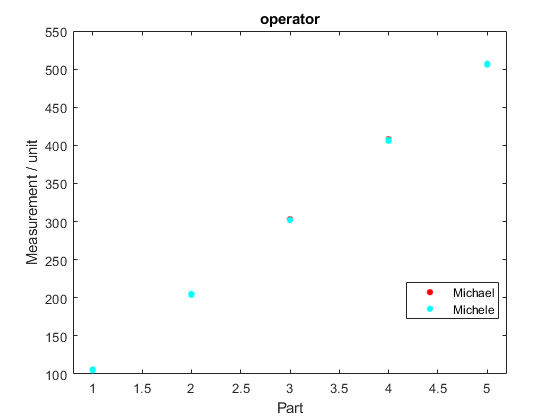


gscatter(data_ms2_michael.Part,data_ms2_michael.Measurement,data_ms2_michael.Operator)
xlabel("Part")
ylabel("Measurement / unit")
title("operator")

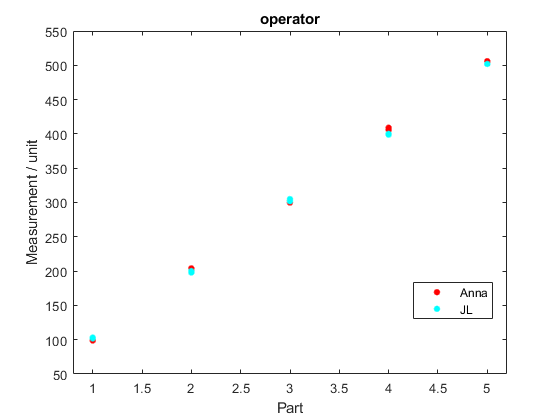


gscatter(data_ms2_anna.Part,data_ms2_anna.Measurement,data_ms2_anna.Operator)
xlabel("Part")
ylabel("Measurement / unit")
title("operator")

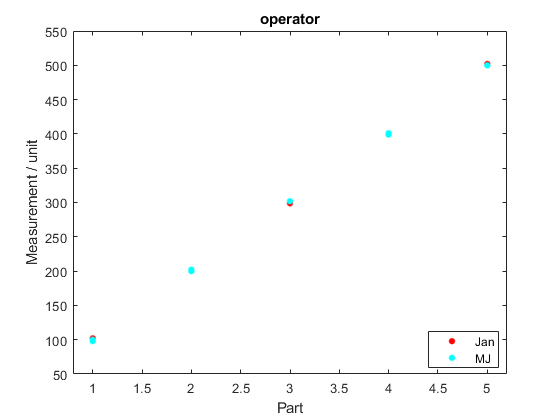


gscatter(data_ms2_jan.Part,data_ms2_jan.Measurement,data_ms2_jan.Operator)
xlabel("Part")
ylabel("Measurement / unit")
title("operator")

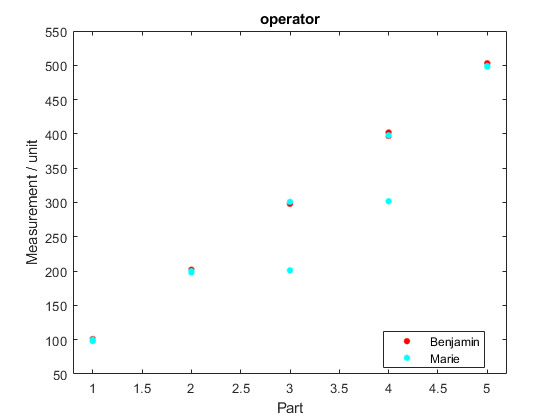


gscatter(data_ms2_benni.Part,data_ms2_benni.Measurement,data_ms2_benni.Operator)
xlabel("Part")
ylabel("Measurement / unit")
title("operator")

%Boxplot
hold off

% @michael kannst du die Farben einfügen, bei meinem Matlab funzt es nicht
boxplot(data_ms2_michael.Measurement,{data_ms2_michael.Part,data_ms2_michael.Operator})
legend(findobj(gca,'Tag','Box'),'Michele','Michael')

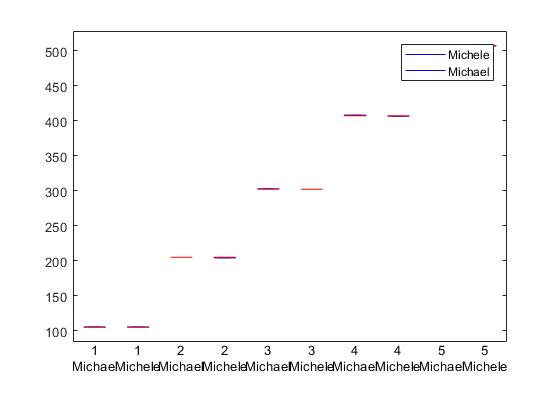

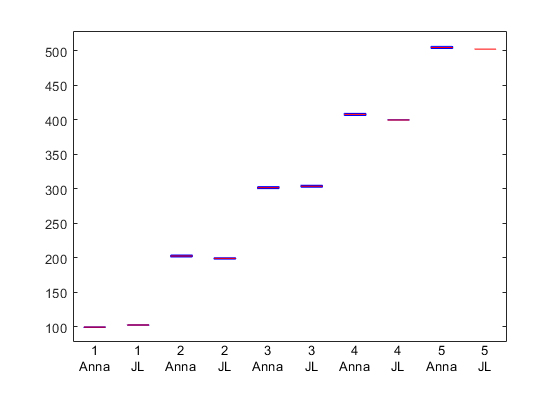


boxplot(data_ms2_anna.Measurement,{data_ms2_anna.Part,data_ms2_anna.Operator})

legend(findobj(gca,'Tag','Box'),'Anna','JL')


boxplot(data_ms2_jan.Measurement,{data_ms2_jan.Part,data_ms2_jan.Operator})
legend(findobj(gca,'Tag','Box'),'Jan','MJ')

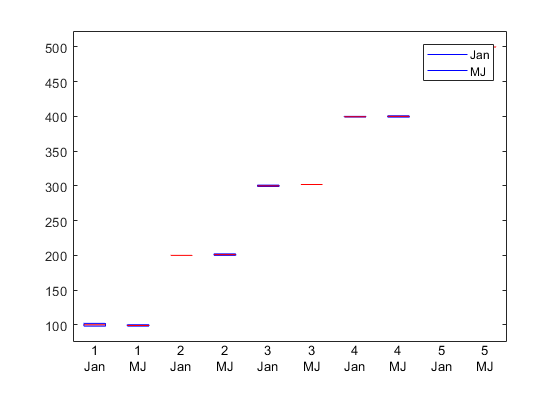

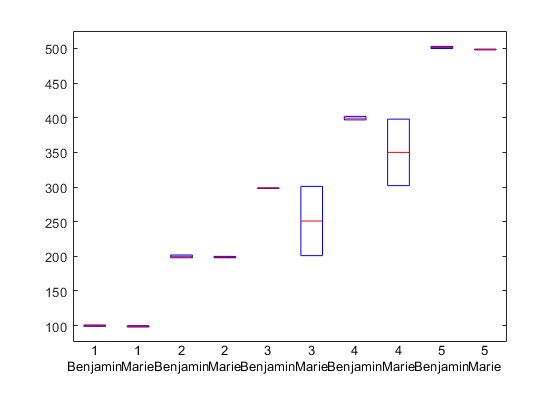


boxplot(data_ms2_benni.Measurement,{data_ms2_benni.Part,data_ms2_benni.Operator})

legend(findobj(gca,'Tag','Box'),'Benjamin','Marie')

hold on

% GageErr
%GageR&R durchführen
hold on
gagerr(data_ms2_michael.Measurement,{data_ms2_michael.Part,data_ms2_michael.Operator})

    'Source'               'Variance'      '% Variance'    'sigma'       '5.15*sigma'    '% 5.15*sigma'
    'Gage R&R'             [    0.2500]    [9.8961e-04]    [  0.5000]    [    2.5750]    [      0.3146]
    '  Repeatability'      [    0.2083]    [8.2468e-04]    [  0.4564]    [    2.3506]    [      0.2872]
    '  Reproducibility'    [    0.0417]    [1.6494e-04]    [  0.2041]    [    1.0512]    [      0.1284]
    '   Operator'          [    0.0417]    [1.6494e-04]    [  0.2041]    [    1.0512]    [      0.1284]
    'Part'                 [2.5262e+04]    [   99.9990]    [158.9406]    [  818.5441]    [     99.9995]
    'Total'                [2.5262e+04]    [       100]    [158.9414]    [  818.5481]    ''            

Number of distinct categories (NDC):450
% of Gage R&R of total variations (PRR):  0.31
Note: The last column of the above table does not have to sum to 100%


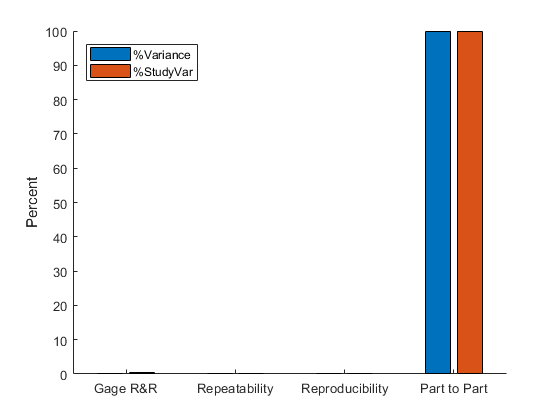

legend('Location',"northwest")
hold off


gagerr(data_ms2_anna.Measurement,{data_ms2_anna.Part,data_ms2_anna.Operator})

    'Source'               'Variance'      '% Variance'    'sigma'       '5.15*sigma'    '% 5.15*sigma'
    'Gage R&R'             [    8.3893]    [    0.0331]    [  2.8964]    [   14.9166]    [      1.8184]
    '  Repeatability'      [    7.5214]    [    0.0296]    [  2.7425]    [   14.1240]    [      1.7218]
    '  Reproducibility'    [    0.8679]    [    0.0034]    [  0.9316]    [    4.7977]    [      0.5849]
    '   Operator'          [    0.8679]    [    0.0034]    [  0.9316]    [    4.7977]    [      0.5849]
    'Part'                 [2.5362e+04]    [   99.9669]    [159.2552]    [  820.1644]    [     99.9835]
    'Total'                [2.5371e+04]    [       100]    [159.2816]    [  820.3000]    ''            

Number of distinct categories (NDC):78
% of Gage R&R of total variations (PRR):  1.82
Note: The last column of the above table does not have to sum to 100%


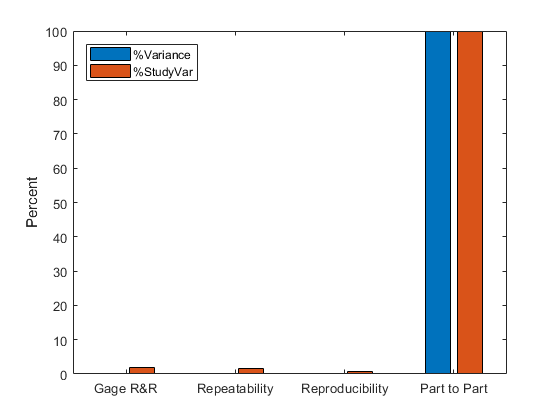

legend('Location',"northwest")


gagerr(data_ms2_jan.Measurement,{data_ms2_jan.Part,data_ms2_jan.Operator})

    'Source'               'Variance'      '% Variance'    'sigma'       '5.15*sigma'    '% 5.15*sigma'
    'Gage R&R'             [    1.8071]    [    0.0072]    [  1.3443]    [    6.9231]    [      0.8487]
    '  Repeatability'      [    1.8071]    [    0.0072]    [  1.3443]    [    6.9231]    [      0.8487]
    '  Reproducibility'    [         0]    [         0]    [       0]    [         0]    [           0]
    '   Operator'          [         0]    [         0]    [       0]    [         0]    [           0]
    'Part'                 [2.5087e+04]    [   99.9928]    [158.3902]    [  815.7097]    [     99.9964]
    'Total'                [2.5089e+04]    [       100]    [158.3959]    [  815.7391]    ''            

Number of distinct categories (NDC):167
% of Gage R&R of total variations (PRR):  0.85
Note: The last column of the above table does not have to sum to 100%


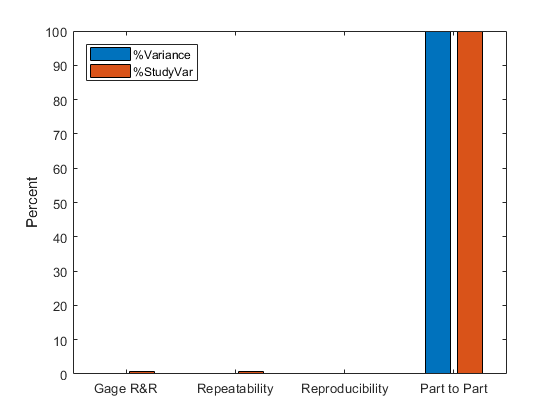

legend('Location',"northwest")


gagerr(data_ms2_benni.Measurement,{data_ms2_benni.Part,data_ms2_benni.Operator})

    'Source'               'Variance'      '% Variance'    'sigma'       '5.15*sigma'    '% 5.15*sigma'
    'Gage R&R'             [  997.2964]    [    4.0251]    [ 31.5800]    [  162.6370]    [     20.0627]
    '  Repeatability'      [  876.9071]    [    3.5392]    [ 29.6126]    [  152.5050]    [     18.8128]
    '  Reproducibility'    [  120.3893]    [    0.4859]    [ 10.9722]    [   56.5069]    [      6.9706]
    '   Operator'          [  120.3893]    [    0.4859]    [ 10.9722]    [   56.5069]    [      6.9706]
    'Part'                 [2.3780e+04]    [   95.9749]    [154.2062]    [  794.1622]    [     97.9668]
    'Total'                [2.4777e+04]    [       100]    [157.4067]    [  810.6444]    ''            

Number of distinct categories (NDC):7
% of Gage R&R of total variations (PRR): 20.06
Note: The last column of the above table does not have to sum to 100%


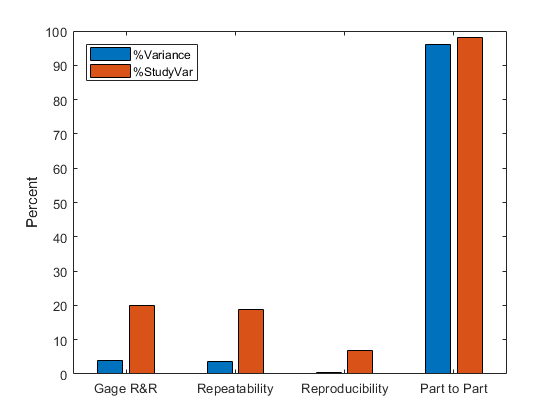

legend('Location',"northwest")


% @Frau Neff bei Fehlern kommentieren


